# `CircularNetFlow`** Examples**

**Overview**

The `CircularNetFlowChart` creates a circular chart representing the net flow between pairs of categories. There are finitely many categories arranged around the circle. The outer ring of the chart contains circular arcs with size representing the net flow from each category. The inner component of the chart contains nodes with size representing the net flow received by each category. The chart data comprises a table `LinkData`, with the following specifications.

- The table contents `A = LinkData{:, :}` is a square, nonnegative numeric 2-D matrix in which `A(i, j)` contains the (gross) flow from category `i` to category `j`. The number of rows and columns of `A` is equal to the number of categories. The diagonal elements of `A` are all zero, indicating that there is no self-flow from a category to itself.

- The variable names of the table are the names of the categories.

The chart computes the net flow between each pair of categories from the table `LinkData`, before using the net flow data to update the graphics.

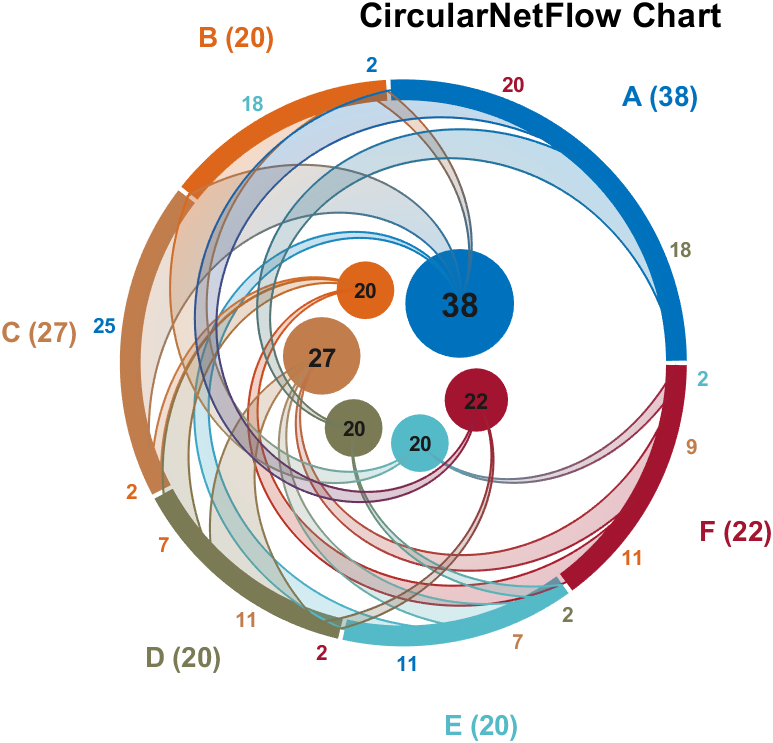

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "CircularNetFlow.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "CircularNetFlow.m"))) the source code for the `CircularNetFlowChart`.

Documentation for:

- [`patch`](matlab: doc("patch")): Plot one or more filled polygonal regions

## Create sample chart data.

Each row of the matrix represents a source ("from") category, and each column represents a sink ("to") category. The matrix element `(i, j)` contains the (gross) flow from category `i` to category `j`. The diagonal elements of the matrix are zero, indicating no self-flow.

n = 6;
linkdata = magic( n );
linkdata(1:n+1:end) = 0;

Create a list of text labels, representing the names of the categories.

labels = ["A", "B", "C", "D", "E", "F"];

Tabulate the link data.

linkdata = array2table( linkdata, "VariableNames", labels );

## Create a figure for the chart.

f = exampleFigure( "Name", "CircularNetFlowChart Example" );

## Create the chart, specifying the parent and input data.

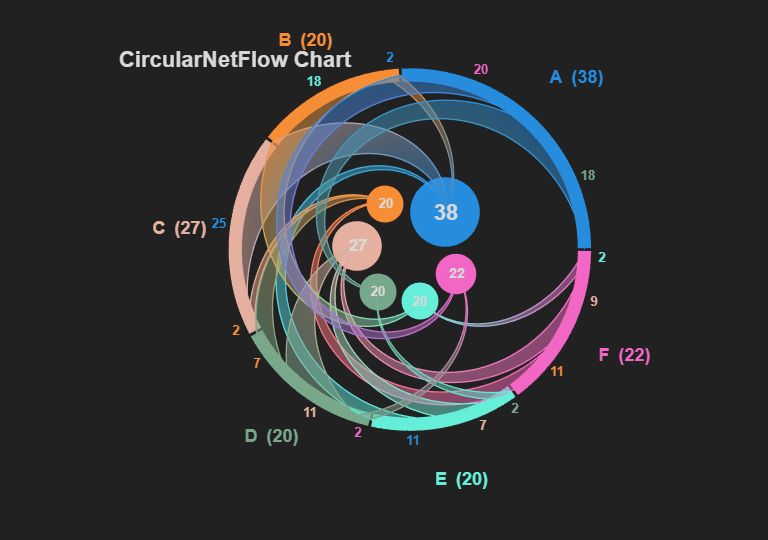

CNFC = CircularNetFlowChart( "Parent", f, ...
    "LinkData", linkdata );

## Adjust the chart title.

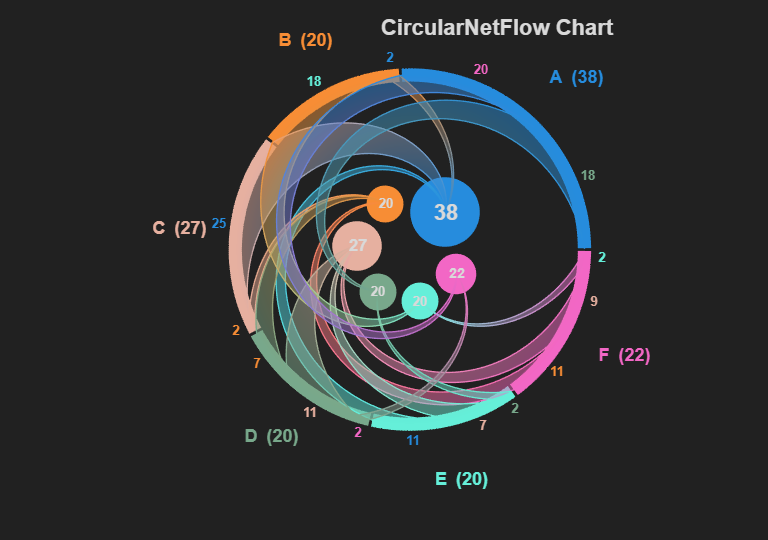

title( CNFC, "CircularNetFlow Chart", "Position", [50, 120, 0] )

## Display the net flow and net sent/received amounts.

disp( CNFC.NetFlow )

          A      B      C      D      E      F 
         ___    ___    ___    ___    ___    ___

    A      0     -2    -25     18    -11     20
    B      2      0     -2     -7     18    -11
    C     25      2      0    -11     -7     -9
    D    -18      7     11      0     -2      2
    E     11    -18      7      2      0     -2
    F    -20     11      9     -2      2      0



disp( "Net amounts sent:" )

Net amounts sent:


disp( CNFC.NetSent )

    38
    20
    27
    20
    20
    22



disp( "Net amounts received: " )

Net amounts received: 


disp( CNFC.NetReceived )

    38
    20
    27
    20
    20
    22



## Adjust the transparency of the chart.

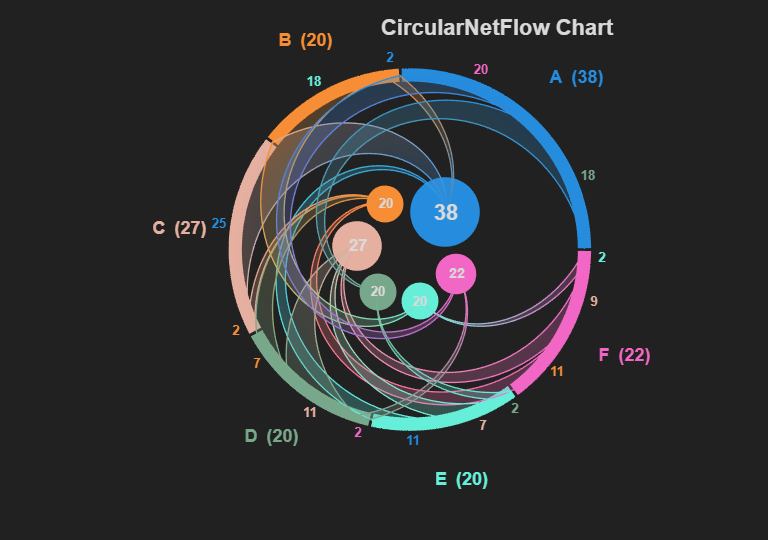

CNFC.FaceAlpha = 0.25;

*Copyright 2018-2025 The MathWorks, Inc.*